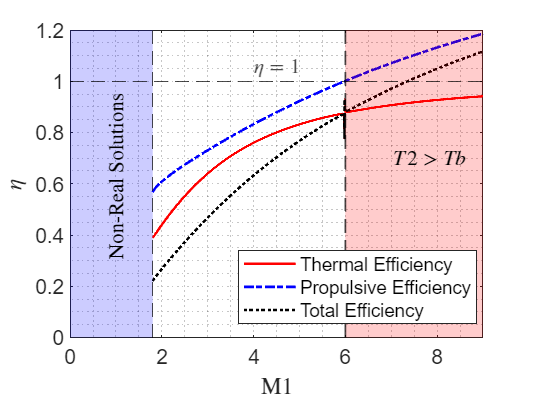

clear
clc

P_1 = 7e4; %ambient pressure
T_1 = 210; %ambient temperature
M_1 = linspace(1.8,9,1900); %free stream mach number
M_x = 1.1; %normal shock strength (before shock mach number)
M_2 = 0.2; %burner entry mach number
T_b = 1700; %maximum burner temperature
Pb_P2 = 1; %burner pressure ratio
P4_P1 = 1; %exhaust pressure ratio
F = 5e5; %required thrust

for i = 1 : length(M_1)
    [A_1(i), A_C1(i), A_2(i), A_b(i), A_C2(i), A_4(i), eta_th(i), eta_p(i)] = RamjetDesign(P_1, T_1, M_1(i), M_x, M_2, T_b, Pb_P2, P4_P1, F);
end

% efficiencies
figure(1)
p1 = plot(M_1,eta_th,'LineWidth',1.5,'color','r','LineStyle','-');
hold on
p2 = plot(M_1,eta_p,'LineWidth',1.5,'color','b','LineStyle','-.');
p3 = plot(M_1, eta_th.* eta_p,'LineWidth',1.5,'color','k','LineStyle',':');
grid minor
xlabel('M1','Interpreter','latex')
ylabel('$\eta$','Interpreter','latex')
l1 = xline(1.8,'k--');
l2 = xline(6,'k--','LineWidth',1);
l3 = yline(1,'k--','$\eta = 1$','Interpreter','latex','FontSize',12,'LabelHorizontalAlignment','center');
f1 = fill([0,1.8,1.8,0],[0,0,1.4,1.4],'b','FaceAlpha',0.2,'LineStyle','none');
f2 = fill([6,12,12,6],[0,0,1.4,1.4],'r','FaceAlpha',0.2,'LineStyle','none');
entries = [p1 p2 p3];
legend(entries,'Thermal Efficiency','Propulsive Efficiency','Total Efficiency','Location','best');
text(7,0.7,'$T2>Tb$','Interpreter','latex','FontSize',12);
text(1,0.3,'Non-Real Solutions','Interpreter','latex','FontSize',12,'Rotation',90)
hold off
set(gca,'FontSize',12);
xlim([0,9])
ylim([0,1.2])